**Task 1**

I = imread("DIP.jpg");

[row, col] = size(I);
T = 1;
a = 0.1;
b = 0.1;
[u , v] = meshgrid(-row/2:row/2-1,-col/2:col/2-1);
H = (T./((pi*(u*a+v*b))+0.00001)).*sin(pi*(u*a+v*b)).*exp(-j*pi*(u*a+v*b));

F = fft2(I);
Fc = fftshift(F);
G = H.*Fc;
gi = ifft2(ifftshift(G));
g = (real(gi));

R = 1./(H+0.00001);
IR = R.*G;
Iri = ifft2(ifftshift(IR));
Ir = (real(Iri));
MSEblurred = immse(abs(g),double(I))

MSEblurred = 1.6934e+04

MSErestored = immse(abs(Ir),double(I))

MSErestored = 1.6331e+04

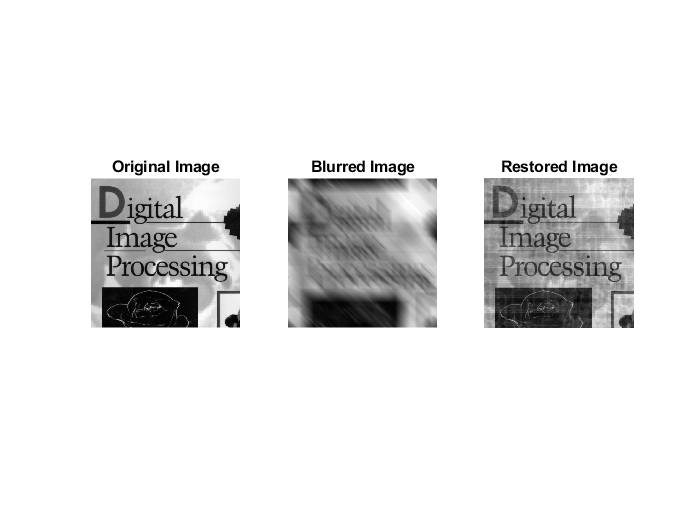


subplot(131), imshow(I), title('Original Image');
subplot(132), imshow(g,[]), title('Blurred Image');
subplot(133), imshow(Ir,[]), title('Restored Image');

**Task 2**

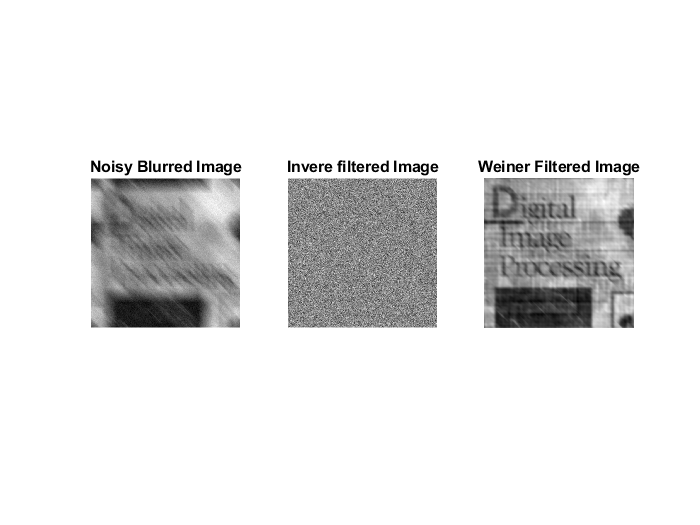

m = 0;
vari = 50;
noise = sqrt(vari).*randn(row,col)+m;

gnoise = g + noise;
F3 = fft2(gnoise);
Fc3 = fftshift(F3);
%GN = H.*Fc3;
GNR = R.*Fc3;
Gnri = ifft2(ifftshift(GNR));
Gnr = real(Gnri);

k = ((abs(fftshift(fft2(noise)))).^2)./((abs(G)).^2);

W = R.*(((conj(H).*H))./(((conj(H).*H))+k)).*Fc3;
Wnri = ifft2(ifftshift(W));
Wnr = (real(Wnri));

figure()
subplot(131), imshow(gnoise,[]), title('Noisy Blurred Image');
subplot(132), imshow(Gnr,[]), title('Invere filtered Image');
subplot(133), imshow(Wnr,[]), title('Weiner Filtered Image');

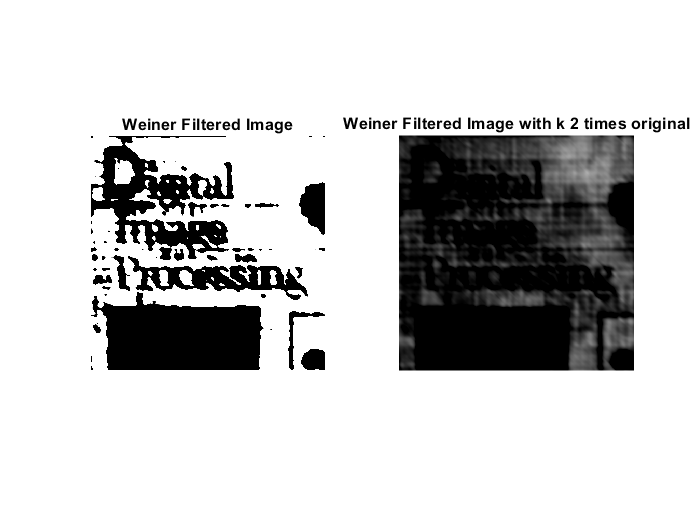


k1 = 2.*k;

W1 = R.*(((abs(H)).^2)./(((abs(H)).^2)+k1)).*Fc3;
Wnri1 = ifft2(ifftshift(W1));
Wnr1 = uint8(real(Wnri1));

k2 = 5.*k;
W2 = R.*(((abs(H)).^2)./(((abs(H)).^2)+k2)).*Fc3;
Wnri2 = ifft2(ifftshift(W2));
Wnr2 = uint8(real(Wnri2));

k3 = 0.5.*k;
W3 = R.*(((abs(H)).^2)./(((abs(H)).^2)+k3)).*Fc3;
Wnri3 = ifft2(ifftshift(W3));
Wnr3 = uint8(real(Wnri));

figure()
subplot(121), imshow(Wnr), title('Weiner Filtered Image');
subplot(122), imshow(Wnr1), title('Weiner Filtered Image with k 2 times original');

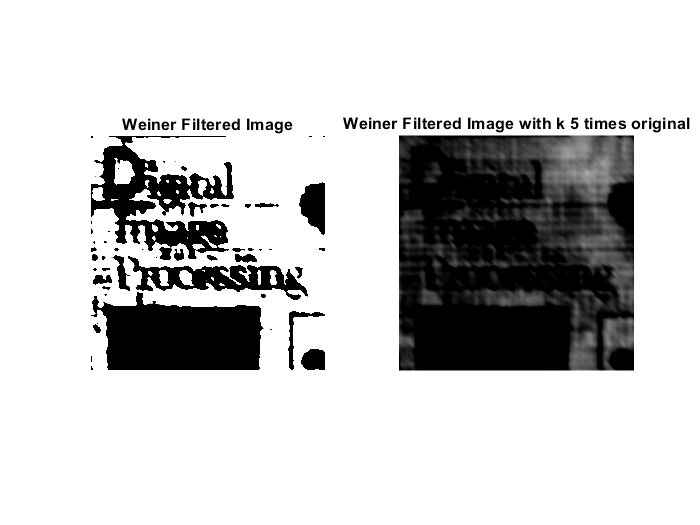


figure()
subplot(121), imshow(Wnr), title('Weiner Filtered Image');
subplot(122), imshow(Wnr2), title('Weiner Filtered Image with k 5 times original');

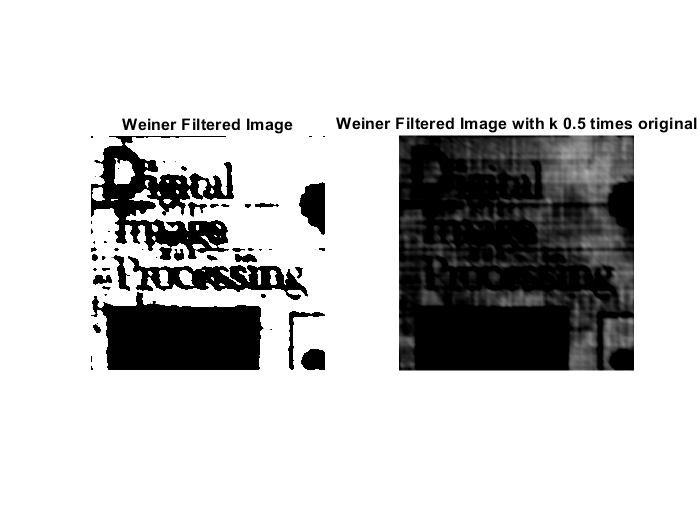


figure()
subplot(121), imshow(Wnr), title('Weiner Filtered Image');
subplot(122), imshow(Wnr3), title('Weiner Filtered Image with k 0.5 times original');